# Opgave 1: Gram-Schmidt

#### Oefening 3

m = 200;
n = 60;

B = randn(m,n);
[Q,~] = qr(B,0);

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V

A =    -0.0935   -0.1355   -0.1135   -0.1029   -0.0925   -0.0910   -0.0940   -0.0941   -0.0933   -0.0935   -0.0934   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935   -0.0935
   -0.0253   -0.0372   -0.0223   -0.0280   -0.0243   -0.0263   -0.0247   -0.0251   -0.0252   -0.0256   -0.0254   -0.0254   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0.0253   -0

#### Oefening 4

e1 = zeros(n, 1);
e2 = zeros(n, 1);

[Q1,~] = klGS(A)

Q1 =    -0.0935   -0.0841   -0.0803   -0.0759    0.0154    0.0788   -0.0343   -0.0785    0.0493   -0.0313    0.0315   -0.0647    0.0051    0.0666   -0.0428    0.0456    0.0738    0.0046   -0.0628   -0.0207   -0.0111    0.0564    0.0440    0.0613   -0.0636    0.0355    0.0039   -0.0748    0.1311    0.1210    0.1193    0.1229    0.1220    0.1221    0.1220    0.1220    0.1220    0.1220    0.1220    0.1220    0.1220    0.1220    0.1220    0.1220    0.1220    0.1220    0.1220    0.1220    0.1220    0.1220
   -0.0253   -0.0237    0.0122   -0.0212    0.0162   -0.0314    0.0386    0.0309    0.0315   -0.1289   -0.0753   -0.1165   -0.0060    0.0196    0.0476    0.0386   -0.0479   -0.0618   -0.0767   -0.0817   -0.0038   -0.0787    0.1602    0.0715    0.0308   -0.0358   -0.0463   -0.0302    0.0734    0.0758    0.0755    0.0729    0.0732    0.0732    0.0732    0.0731    0.0731    0.0731    0.0731    0.0731    0.0731    0.0731    0.0731    0.0731    0.0731    0.0731    0.0731    0.0731    0.0731    

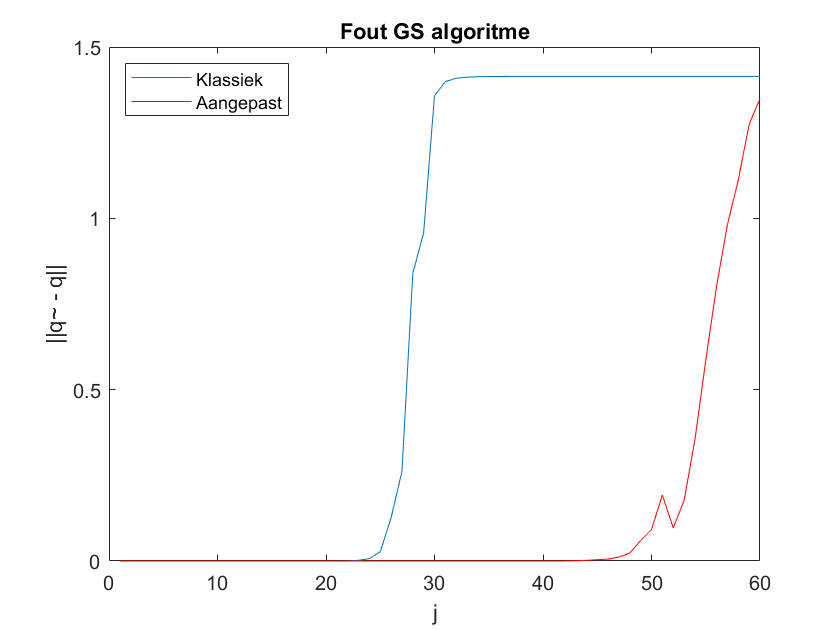

[Q2,~] = modGS(A);

for j = 1:n
    e1(j, 1) = norm(Q1(:,j)-Q(:,j));
    e2(j, 1) = norm(Q2(:,j)-Q(:,j));
end

% linear scale plot
plot(e1)
hold on
plot(e2,'Color','r')
hold off
title("Fout GS algoritme")
xlabel('j')
ylabel('||q~ - q||')
legend('Klassiek','Aangepast','Location','northwest')

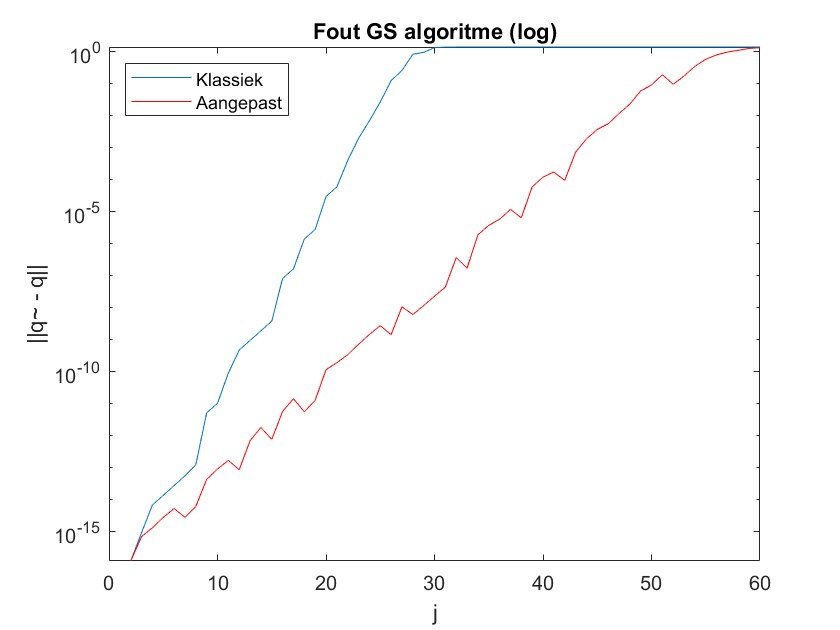


% logarithmic scale plot
plot(e1)
hold on
plot(e2,'Color','r')
hold off
title("Fout GS algoritme (log)")
xlabel('j')
ylabel('||q~ - q||')
legend('Klassiek','Aangepast','Location','northwest')
set(gca, 'YScale', 'log')

#### Oefening 8

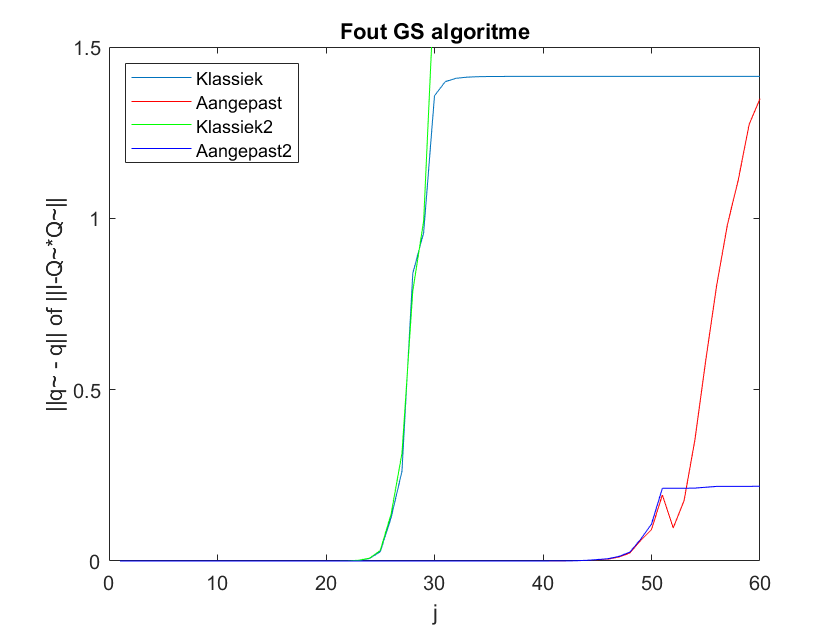

orth1 = zeros(n, 1);
orth2 = zeros(n, 1);

for j = 1:n
    orth1(j, 1) = norm(eye(j) - Q1(:,1:j)'*Q1(:,1:j));
    orth2(j, 1) = norm(eye(j) - Q2(:,1:j)'*Q2(:,1:j));
end

plot(e1)
hold on
plot(e2,'Color','r')
hold on
plot(orth1, 'Color', 'g')
hold on
plot(orth2,'Color','b')
hold off
title("Fout GS algoritme")
xlabel('j')
ylabel('||q~ - q|| of ||I-Q~*Q~||')
legend('Klassiek','Aangepast', 'Klassiek2', 'Aangepast2', 'Location','northwest')
axis([0 60 0 1.5])

#### Oefening 5

m = 200;
n = 3;

B = randn(m,n);
[Q,~] = qr(B,0); 

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V 

A =    -0.0368    0.0425   -0.0358
    0.0688    0.0448    0.0613
    0.0227   -0.0139   -0.0018
    0.0740    0.0382    0.0638
   -0.1083   -0.1032   -0.0992
    0.0144    0.0602   -0.0148
   -0.1258   -0.1325   -0.1438
    0.0236    0.0064    0.0325
   -0.0696   -0.0280   -0.0815
    0.0250    0.0367    0.0319


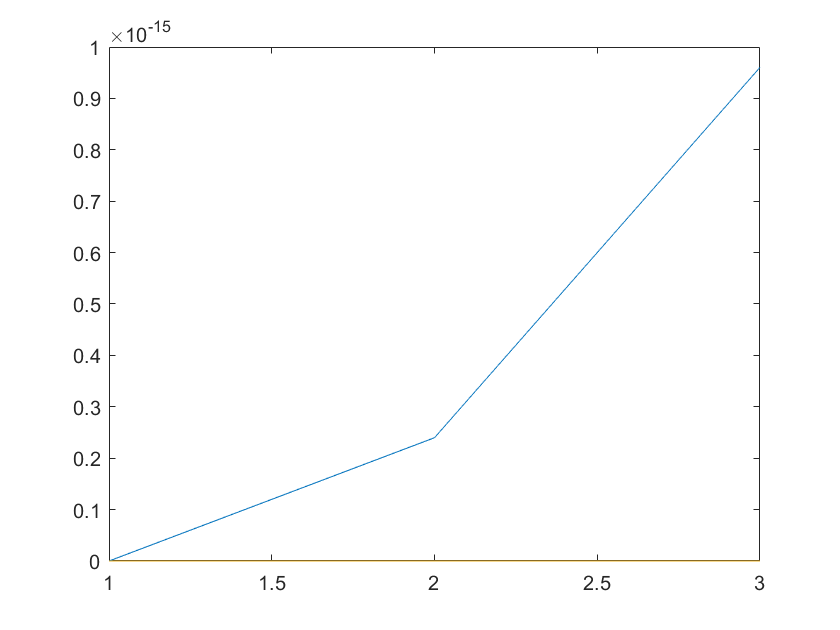


e1 = zeros(n);
[Q1,~] = klGS(A);
for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
end
plot(e1)

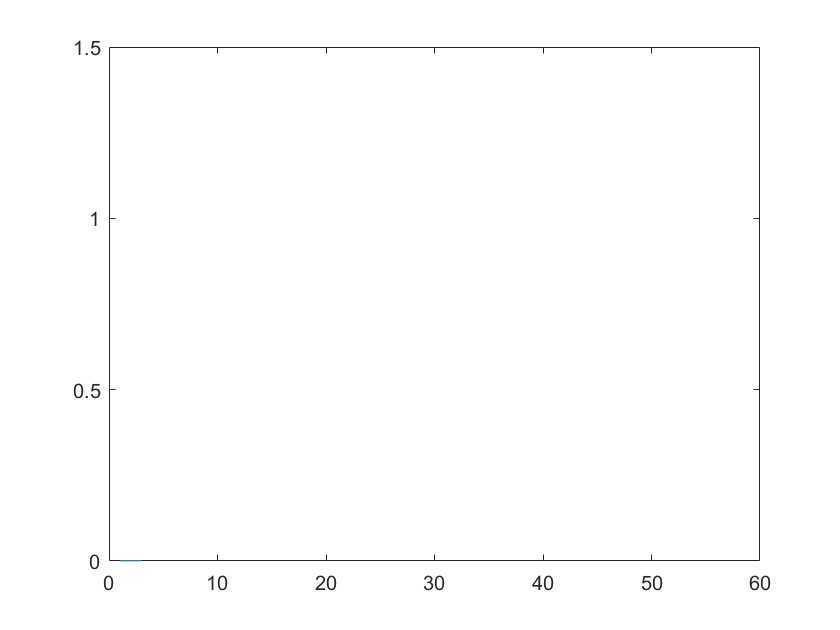


% comparison of theoretical error (te) with experimental error (e)
te1 = zeros(n);
te2 = zeros(n);
x = zeros(1,n);
for j = 1:n
    x(j) = 2^(j-1);
    te1(j) = 2^(j-1)*norm(x)*eps;
    te2(j) = 2^(j-1)*eps;
end
plot(te1)
hold on
plot(te2)
hold off
axis([0 60 0 1.5])

#### Oefening 9

m = 200;
n = 50;
k = 1:50;

B = randn(m,n);
[Q,~] = qr(B,0);

[V,~] = qr(rand(n));
V = 10*rand*V;

D = zeros(n);
for i = k
    D(:,:,i) = diag(2.^linspace(0,i,n));
end
D;

A = zeros(m, n);
for i = k
    A(:,:,i) = Q*D(:,:,i)*V;
end
A;

K = zeros(length(k), 1);
for i = k
    K(i) = norm(A(:,:,i)) * norm(pinv(A(:,:,i)));
end
K

K = 	1.0e+13 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


#### Oefening 10

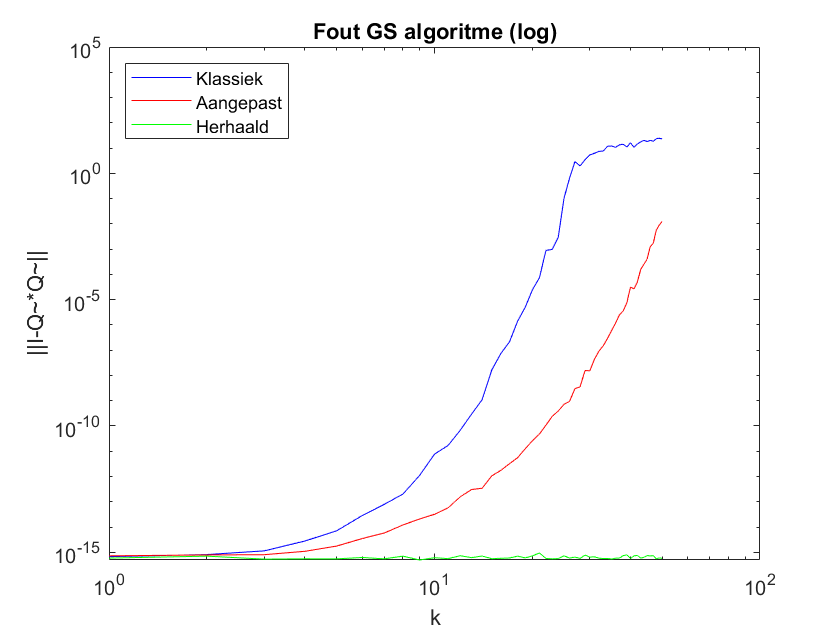

Q1 = zeros(m, n);
for i = k
    [Q1(:,:,i),~] = klGS(A(:,:,i));
end
Q1;

Q2 = zeros(m, n);
for i = k
    [Q2(:,:,i),~] = modGS(A(:,:,i));
end
Q2;

Q3 = zeros(m, n);
for i = k
    [Q3(:,:,i),~] = herGS(A(:,:,i));
end
Q3;

orth1 = zeros(length(k), 1);
for i = k
    orth1(i) = norm(eye(n) - Q1(:,:,i)'*Q1(:,:,i));
end
orth1;

orth2 = zeros(length(k), 1);
for i = k
    orth2(i) = norm(eye(n) - Q2(:,:,i)'*Q2(:,:,i));
end
orth2;

orth3 = zeros(length(k), 1);
for i = k
    orth3(i) = norm(eye(n) - Q3(:,:,i)'*Q3(:,:,i));
end
orth3;

loglog(k, orth1, 'b', k, orth2, 'r', k, orth3, 'g')
hold off
title("Fout GS algoritme (log)")
xlabel('k')
ylabel('||I-Q~*Q~||')
legend('Klassiek','Aangepast', 'Herhaald', 'Location','northwest')

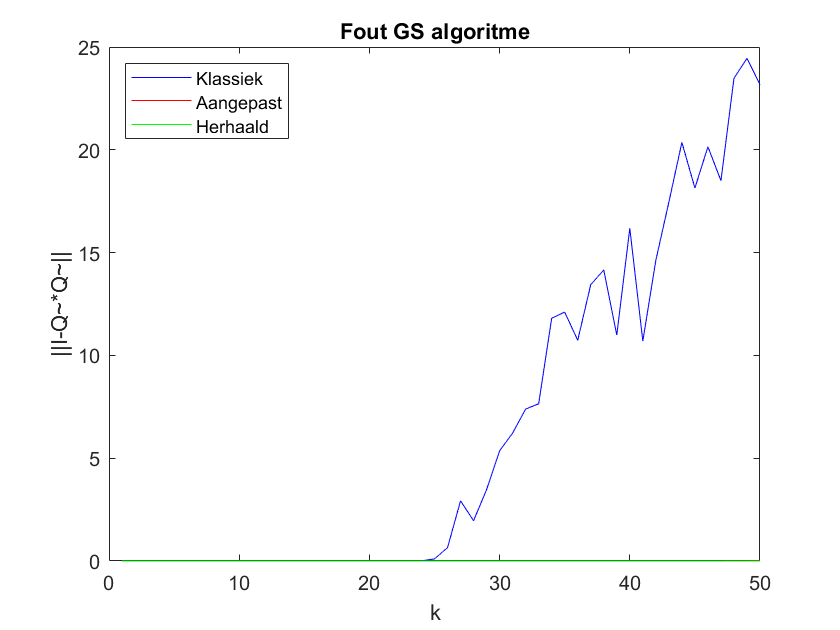

plot(k, orth1, 'b', k, orth2, 'r', k, orth3, 'g')
hold off
title("Fout GS algoritme")
xlabel('k')
ylabel('||I-Q~*Q~||')
legend('Klassiek','Aangepast', 'Herhaald', 'Location','northwest')

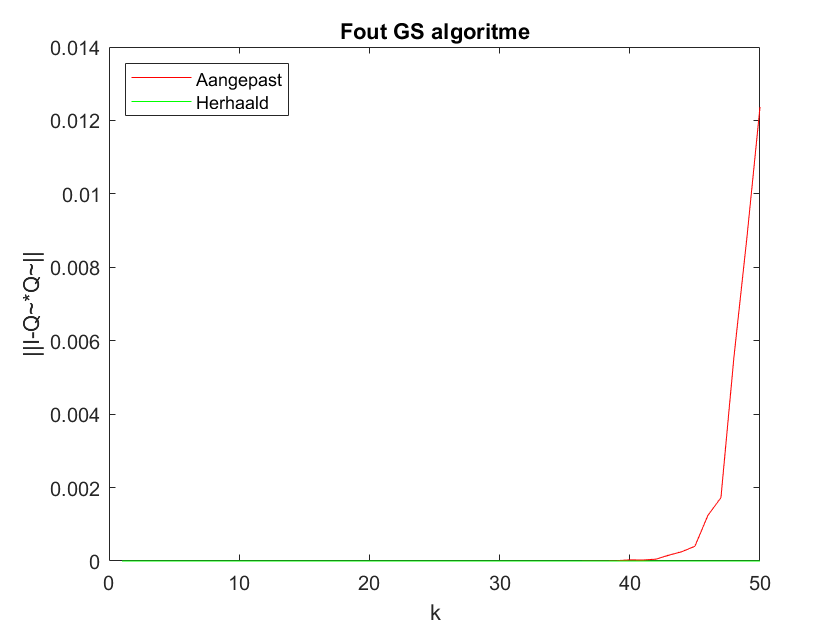

plot(k, orth2, 'r', k, orth3, 'g')
hold off
title("Fout GS algoritme")
xlabel('k')
ylabel('||I-Q~*Q~||')
legend('Aangepast', 'Herhaald', 'Location','northwest')

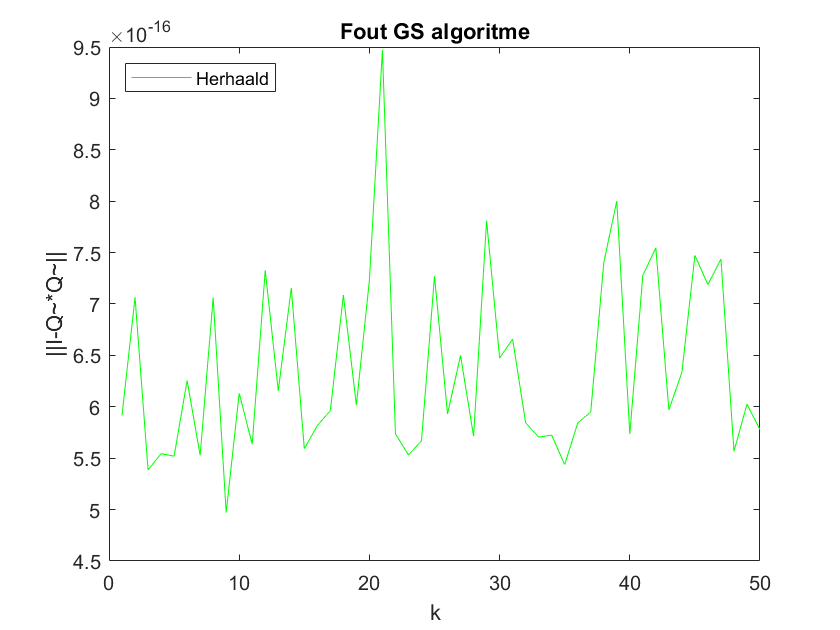

plot(k, orth3, 'g')
hold off
title("Fout GS algoritme")
xlabel('k')
ylabel('||I-Q~*Q~||')
legend('Herhaald', 'Location','northwest')


rorth1 = zeros(50, 1);
rorth2 = zeros(50, 1);
rorth3 = zeros(50, 1);
for i=k
    rorth1(i) = log( (orth1(i)) /( 2^(-52) ) ) /log(K(i));
    rorth2(i) = log( (orth2(i)) /( 2^(-52) ) ) /log(K(i));
    rorth3(i) = log( (orth3(i)) /( 2^(-52) ) ) /log(K(i));
end
rorth1

rorth1 =     1.6007
    0.9391
    0.7882
    0.9155
    0.9985
    1.1688
    1.2099
    1.2294
    1.3651
    1.5085


rorth2

rorth2 =     1.7113
    0.9136
    0.6206
    0.5774
    0.5981
    0.6641
    0.6717
    0.7217
    0.7287
    0.7172


rorth3

rorth3 =     1.4144
    0.8350
    0.4262
    0.3300
    0.2627
    0.2491
    0.1880
    0.2087
    0.1292
    0.1466


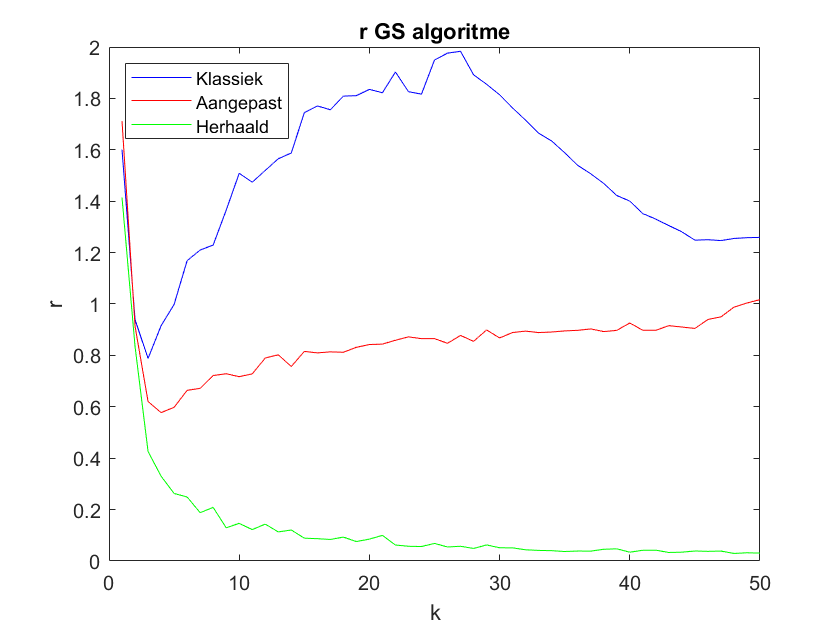


plot(k, rorth1, 'b', k, rorth2, 'r', k, rorth3, 'g')
hold off
title("r GS algoritme")
xlabel('k')
ylabel('r')
legend('Klassiek','Aangepast', 'Herhaald', 'Location','northwest')

# Opgave 2: Iteratieve methoden

A = sprand(1000,1000, 100);
n = length(A);
m = 100;
v = rand(n,1);

ritzvaluesiterations = zeros(m, 6);
for i=1:m
    [V,H] = Arnoldi(A,v,i);
    Hn = H(1:i, :);
    [~, ritzvalues] = eigs(Hn);
    for k=1:length(ritzvalues)
        ritzvaluesiterations(i, k) = ritzvalues(k, k);
    end
end

[V,H] = Arnoldi(A,v,m);

colors = ['g', 'b', 'c', 'r', 'm', 'y']

colors = 'gbcrmy'

eigenvalues = zeros(6, 1);
[~, eigenvaluesdiagonal] = eigs(A);

for eigenvalue=1:6
    eigenvalues(eigenvalue) = eigenvaluesdiagonal(eigenvalue, eigenvalue);
    plot(real(eigenvalues(eigenvalue)), imag(eigenvalues(eigenvalue)), 'x', "MarkerSize",20, "Color", colors(eigenvalue))
    hold on
end

eigenvalues

eigenvalues = 	1.0e+02 *

   3.1577 + 0.0000i
   0.0980 + 0.0419i
   0.0980 - 0.0419i
   0.0285 + 0.1025i
   0.0285 - 0.1025i
      NaN + 0.0000i


ritzvaluesiterations;
Hn = H(1:m, :);
[~, ritzvalues] = eigs(Hn);

ritz1 = ritzvaluesiterations(:, 1)

ritz1 =   235.2316
  315.6407
  315.7666
  315.7670
  315.7671
  315.7671
  315.7671
  315.7671
  315.7671
  315.7671


ritz2 = ritzvaluesiterations(:, 2)

ritz2 =    0.0000 + 0.0000i
  -0.6037 + 0.0000i
  -0.5212 + 1.7568i
  -3.3071 + 0.0000i
   2.9303 + 4.3096i
  -4.0674 + 3.3924i
  -5.5160 + 3.5673i
   5.3430 + 4.4121i
  -5.7021 + 5.6203i
  -6.0061 + 5.8891i


ritz3 = ritzvaluesiterations(:, 3)

ritz3 =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.5212 - 1.7568i
   0.7958 + 2.5298i
   2.9303 - 4.3096i
  -4.0674 - 3.3924i
  -5.5160 - 3.5673i
   5.3430 - 4.4121i
  -5.7021 - 5.6203i
  -6.0061 - 5.8891i


ritz4 = ritzvaluesiterations(:, 4)

ritz4 =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.7958 - 2.5298i
  -3.9459 + 3.2317i
   3.1214 + 3.8754i
   4.2065 + 4.0249i
  -4.4856 + 4.0381i
  -0.3352 + 7.6328i
  -8.2893 + 0.0000i


ritz5 = ritzvaluesiterations(:, 5)

ritz5 =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -3.9459 - 3.2317i
   3.1214 - 3.8754i
   4.2065 - 4.0249i
  -4.4856 - 4.0381i
  -0.3352 - 7.6328i
  -0.6072 + 8.1864i


ritz6 = ritzvaluesiterations(:, 6)

ritz6 =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.2080 + 0.0000i
   0.1225 + 5.3218i
  -0.0148 + 5.7527i
   5.3663 + 5.3147i
  -0.6072 - 8.1864i


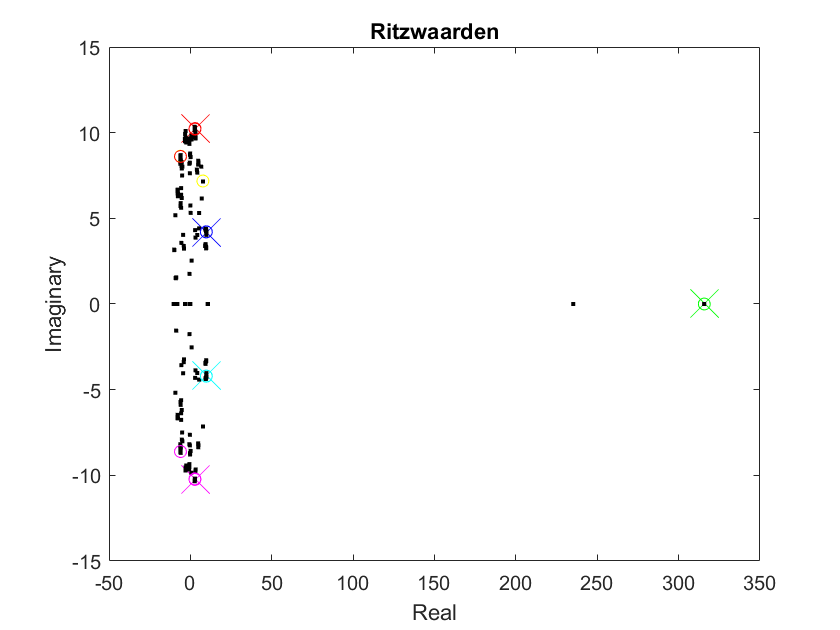

for k=1:100
    if k < 91
        plot(real(ritz1(k)), imag(ritz1(k)), '.', 'Color', 'k')
        plot(real(ritz2(k)), imag(ritz2(k)), '.', 'Color', 'k')
        plot(real(ritz3(k)), imag(ritz3(k)), '.', 'Color', 'k')
        plot(real(ritz4(k)), imag(ritz4(k)), '.', 'Color', 'k')
        plot(real(ritz5(k)), imag(ritz5(k)), '.', 'Color', 'k')
        plot(real(ritz6(k)), imag(ritz6(k)), '.', 'Color', 'k')
    end
    if k >= 91
        plot(real(ritz1(k)), imag(ritz1(k)), 'o', 'Color', colors(1))
        plot(real(ritz2(k)), imag(ritz2(k)), 'o', 'Color', colors(2))
        plot(real(ritz3(k)), imag(ritz3(k)), 'o', 'Color', colors(3))
        plot(real(ritz4(k)), imag(ritz4(k)), 'o', 'Color', colors(4))
        plot(real(ritz5(k)), imag(ritz5(k)), 'o', 'Color', colors(5))
        plot(real(ritz6(k)), imag(ritz6(k)), 'o', 'Color', colors(6))
    end
    pause(0.1)
end

hold off
title("Ritzwaarden")
xlabel('Real')
ylabel('Imaginary')